# 2-1

clc
close all;
clear

## part b

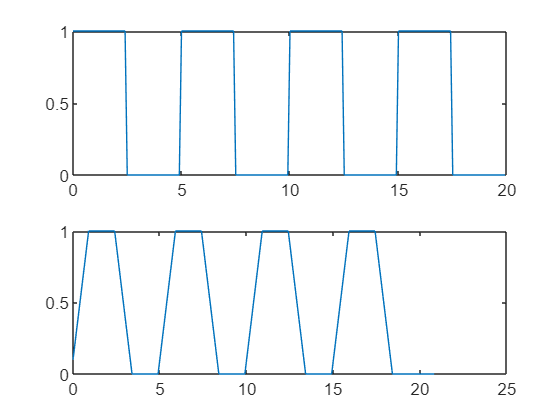


t=0:0.1:19.9;
x=repmat([ones(1,25),zeros(1,25)],1,4);
h1=0.1*ones(1,10);
t1=0:0.1:20.8;
y1=conv(h1,x);
figure()
subplot(2,1,1)
plot(t,x)
subplot(2,1,2)
plot(t1,y1)

## part c

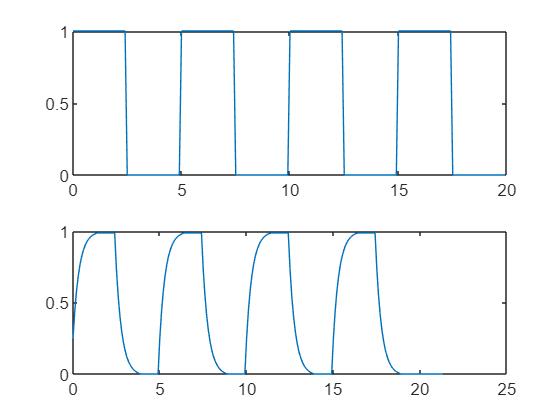

t=0:0.1:19.9;
x=repmat([ones(1,25),zeros(1,25)],1,4);
h2=0.25*ones(1,15);
for n=0:14
    h2(n+1)=h2(n+1)*(0.75)^n;
end
y2=myconv(h2,x);
t2=0:0.1:21.3;
figure()
subplot(2,1,1)
plot(t,x)
subplot(2,1,2)
plot(t2,y2)

## part d

t3=0:0.1:20.4

t3 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


syms z n
H=0.2*(1-z^-1)^5;
h3=ones(1,6);
hd(n)=iztrans(H)

$$hd(n) = 2\,\delta_{n-2,0}-\delta_{n-1,0}-2\,\delta_{n-3,0}+\delta_{n-4,0}-\frac{\delta_{n-5,0}}{5}+\frac{\delta_{n,0}}{5}$$

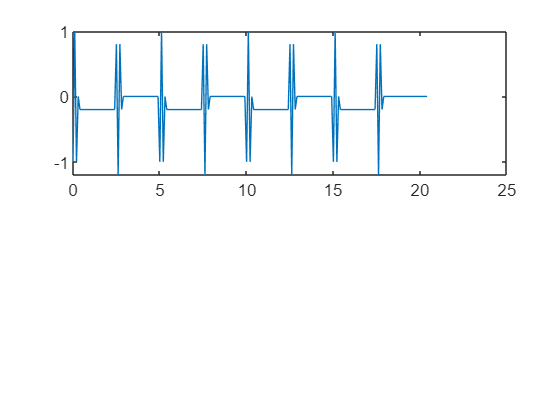

for m=1:6
    h3(m)=hd(m);
end
y3=myconv(h3,x);
figure()
subplot(2,1,1)
plot(t3,y3)

## 2-2

## part a*

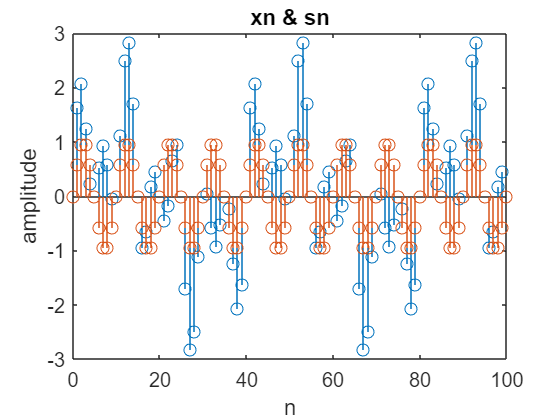

M = 100;
n = 0:M;
w1 = 0.05 * pi;
w2 = 0.2 * pi;
w3 = 0.35 * pi;
sn = sin(w2 * n);
vn = sin(w1 * n) + sin(w3 * n);
xn = sn + vn;
wn=0.54 - 0.46 * sin(2*pi*n/M);
hn = wn.*(4 * sinc(0.25 * (n-M/2)) - (1/0.15)*sinc(0.15 * (n-M/2)));
figure();
stem(n,xn);
hold on;
stem(n,sn);
title('xn & sn')
xlabel('n')
ylabel('amplitude')

## part b*

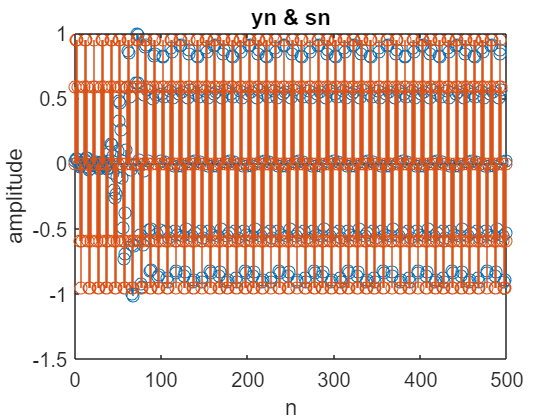

M = 100;
n = 0:500;
m=0:M;
w1 = 0.05 * pi;
w2 = 0.2 * pi;
w3 = 0.35 * pi;
sn = sin(w2 * n);
vn = sin(w1 * n) + sin(w3 * n);
xn = sn + vn;
wn=0.54 - 0.46 * sin(2*pi*m/M);
hn = wn.*(0.25 * sinc(0.25 * (m-M/2)) - (0.15)*sinc(0.15 * (m-M/2)));


H = freqz(hn,1,1024);
hn = hn / max(abs(H));

yn=filter(hn,1,xn);
%yn1=conv(xn,hn,'same');
figure();
stem(n,yn);
hold on;
stem(n,sn);
title('yn & sn')
xlabel('n')
ylabel('amplitude')

## part c

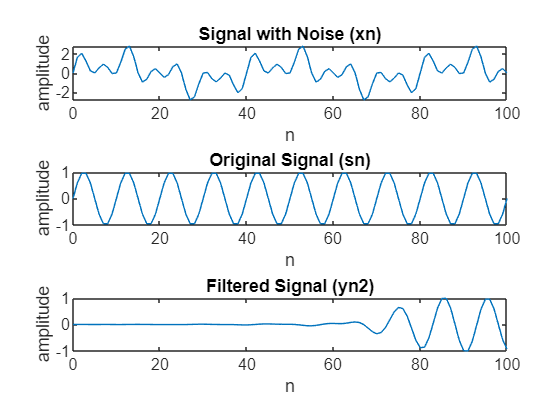

M = 100;
n = 0:200;
w1 = 0.05 * pi;
w2 = 0.2 * pi;
w3 = 0.35 * pi;
sn = sin(w2 * n);
vn = sin(w1 * n) + sin(w3 * n);
xn = sn + vn;





clear; close all; clc;


load('CLS22.mat'); 


filter_coeffs = Num;  

yn2 = filter(filter_coeffs, 1, xn); 



figure();
subplot(3,1,1); plot(n, xn); title('Signal with Noise (xn)');
xlabel('n')
ylabel('amplitude')
subplot(3,1,2); plot(n, sn); title('Original Signal (sn)');
xlabel('n')
ylabel('amplitude')
subplot(3,1,3); plot(n, yn2); title('Filtered Signal (yn2)');
xlabel('n')
ylabel('amplitude')

## 2-3

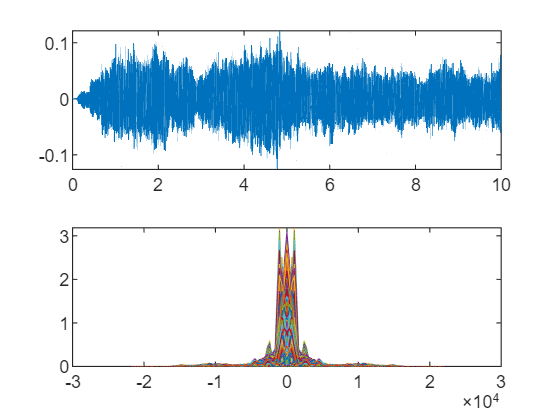

[X,f ]=audioread("Audio01.wav");
time=0:1/f:(length(X)-1)*(1./f);
f0=10000;

figure( )
subplot(2,1,1)
plot(time,X)

X1=X.';
[Fourier , Freq ]=stft(X1,f);

subplot(2,1,2)
plot(Freq,abs(Fourier))

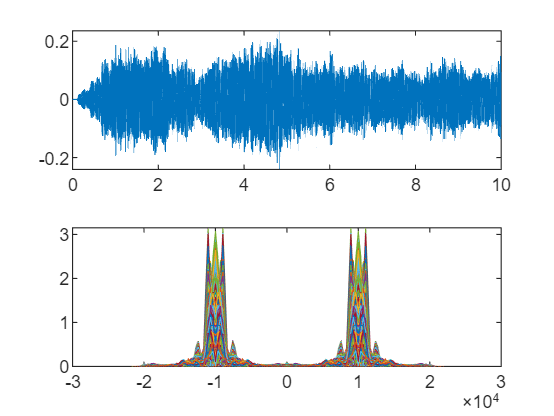



load("myfilter.mat")
c=2*cos(2.*pi*f0*time);
Fx=filter(myfilter,1,X1);
CX=c.*Fx;
[CF , ~]=stft(CX,f);

figure()

subplot(2,1,1)
plot(time,CX)

subplot(2,1,2)
plot(Freq,abs(CF))

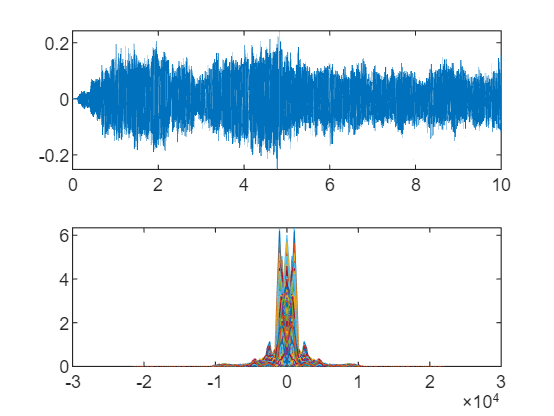


PRX=c.*CX;
RX=filter(myfilter,1,PRX);
[stftRX , ~]=stft(RX,f );


figure()
subplot(2,1,1)
plot(time,RX)

subplot(2,1,2)
plot(Freq,abs(stftRX))

## 2-4

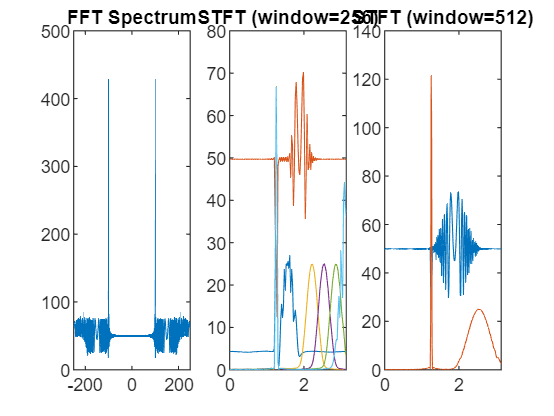

f0=100;
fs=500;
t4=0:1/fs:2;
x4=sin(2*pi*f0*t4) + [zeros(1,249),50,zeros(1,751)] + chirp(t4,400,2,200);
f4=linspace(-250,250,length(t4));
X4=abs(fftshift(fft(x4)));



[s256,f256]=spectrogram(x4,hamming(256));
[s512,f512]=spectrogram(x4,hamming(512));

sx256=abs(s256);
sx512=abs(s512);


figure()
subplot(1,3,1)
plot(f4,X4)
title('FFT Spectrum')

subplot(1,3,2)
plot(f256,sx256)
axis xy
title('STFT (window=256)')


subplot(1,3,3)
plot(f512,sx512)
axis xy
title('STFT (window=512)')

## 2-5

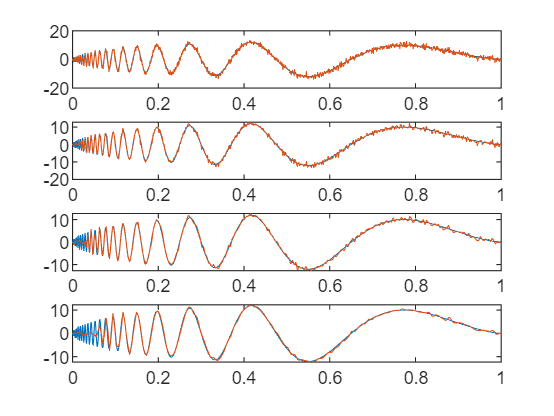

t5=linspace(0,1,1024);
t52=linspace(0,1,512);
t53=linspace(0,1,256);
[x5,nx5]=wnoise('doppler',10,7);


[dx51,dn1]=dwt(nx5,'sym4');
drx51=idwt(dx51,zeros(size(dx51)),'sym4');
ddrx51=downsample(drx51,2);


[dx52,dn2]=dwt(ddrx51,'sym4');
drx52=idwt(dx52,zeros(size(dx52)),'sym4');
ddrx52=downsample(drx52,2);

[dx53,dn3]=dwt(ddrx52,'sym4');
drx53=idwt(dx53,zeros(size(dx53)),'sym4');
ddrx53=downsample(drx53,2);

figure()
subplot(4,1,1)
plot(t5,x5,t5,nx5)

subplot(4,1,2)
plot(t5,x5,t5,drx51)

subplot(4,1,3)
plot(t5,x5,t52,drx52)

subplot(4,1,4)
plot(t5,x5,t53,drx53)

    function y = myconv(h, x)
    % h : impulse response (length M+1)
    % x : input signal (length L+1)
    % y : convolution output of length M+L+1

    M = length(h) - 1;
    L = length(x) - 1;

    % خروجی باید M+L+1 نقطه داشته باشد
    y = zeros(1, M + L + 1);

    % اجرای کانولوشن طبق فرمول درس
    for n = 0 : (M + L)
        s = 0;
        for m = 0 : min(n, M)
            if (n - m) <= L
                s = s + h(m+1) * x(n - m + 1);
            end
        end
        y(n+1) = s;
    end
end
